# Import and plotting a structure

## Import a structure

This is how we import any .gro | .pdb | .xyz file

atom=import_atom('96spc_hex_ice_h.gro');

Found .gro file
.gro file imported
Elapsed time is 0.204045 seconds.


composition = struct with fields:
     resnames: {'SOL'}
    nresidues: 96
       natoms: 288

Atom_types = 1×3 cell array
    'HW1'    'HW2'    'OW'

Atom_numbers =     96    96    96

Box_dim =    13.5212   15.6129   14.7200

..or you could try these commands specific for each filetype

% atom=import_atom_gro('filename.gro');
% atom=import_atom_pdb('filename.pdb');
% atom=import_atom_xyz('filename.xyz'); % any info regarding box size? If not add it manually to the Box_dim 1x3 (1x9 for triclinic) vector

## Now let's plot the imported simulation box

The atom scripts comes with a simple plot function called plot_atom, which can display and rotate a simulation cell in 3D.

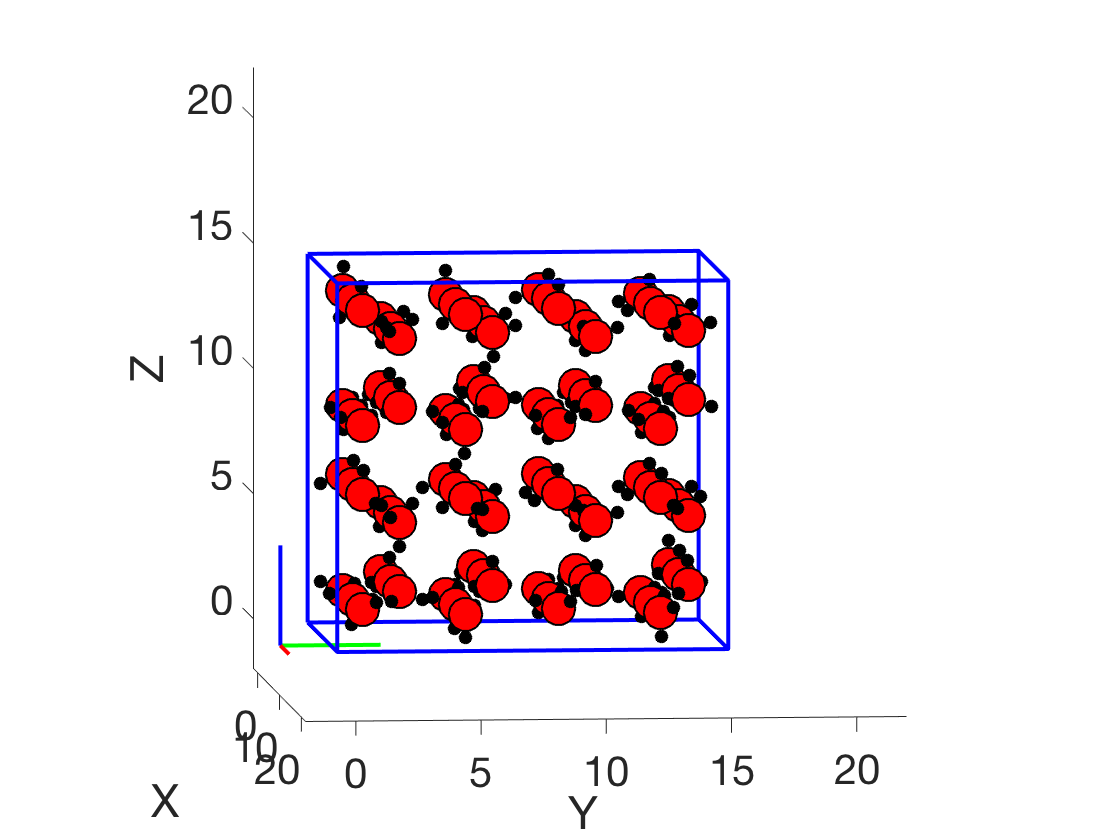

plot_atom(atom,Box_dim,'axis'); % 'axis' argument is optional
view(85,5); % change the default view

However, you could also use VMD if the path in the function PATH2VMD() is set correctly. Note that VMD will lock the matlab editor/parser as long a its open, but can be closed by issuing 'exit' in the command window. Anyway,to run VMD try invoking:

vmd(atom,Box_dim);

Box_dim =    13.5212   15.6129   14.7200

.gro structure file written
Info) VMD for MACOSXX86, version 1.9.2 (December 29, 2014)
Info) http://www.ks.uiuc.edu/Research/vmd/                         
Info) Email questions and bug reports to vmd@ks.uiuc.edu           
Info) Please include this reference in published work using VMD:   
Info)    Humphrey, W., Dalke, A. and Schulten, K., `VMD - Visual   
Info)    Molecular Dynamics', J. Molec. Graphics 1996, 14.1, 33-38.
Info) -------------------------------------------------------------
Info) Multithreading available, 4 CPUs detected.
Info) OpenGL renderer: Intel(R) Iris(TM) Graphics 6100
Info)   Features: STENCIL MDE MTX NPOT PP PS GLSL(OVF) 
Info)   Full GLSL rendering mode is available.
Info)   Textures: 2-D (16384x16384), 3-D (2048x2048x2048), Multitexture (8)
Info) Dynamically loaded 2 plugins in directory:
Info) /Applications/VMD 1.9.2.app/Contents/vmd/plugins/MACOSXX86/molfile
Info) File loading in progress, please wait.
Info) Using plugin gro for structure file temp_out.gro


or plot the file direclty by issuing something like:

% vmd('96spc_hex_ice_h.gro');

Info) VMD for MACOSXX86, version 1.9.2 (December 29, 2014)
Info) http://www.ks.uiuc.edu/Research/vmd/                         
Info) Email questions and bug reports to vmd@ks.uiuc.edu           
Info) Please include this reference in published work using VMD:   
Info)    Humphrey, W., Dalke, A. and Schulten, K., `VMD - Visual   
Info)    Molecular Dynamics', J. Molec. Graphics 1996, 14.1, 33-38.
Info) -------------------------------------------------------------
Info) Multithreading available, 4 CPUs detected.
Info) OpenGL renderer: Intel(R) Iris(TM) Graphics 6100
Info)   Features: STENCIL MDE MTX NPOT PP PS GLSL(OVF) 
Info)   Full GLSL rendering mode is available.
Info)   Textures: 2-D (16384x16384), 3-D (2048x2048x2048), Multitexture (8)
Info) Dynamically loaded 2 plugins in directory:
Info) /Applications/VMD 1.9.2.app/Contents/vmd/plugins/MACOSXX86/molfile
Info) File loading in progress, please wait.
Info) Using plugin gro for structure file 96spc_hex_ice_h.gro
Info) Using plugin gr